# Code Generation for Incremental Learning

This example shows how to generate code that implements incremental learning for binary linear classification. To motivate its purpose, consider training a wearable device tasked to determine whether the wearer is idle or moving,  based on sensory features the device reads.

The generated code performs the following tasks, as defined in entry-point functions:

- Load a configured incremental learning model template created at the command line.

- Track performance metrics on the incoming batch of data from a data stream. This example tracks misclassification rate and hinge loss.

- Update the model by fitting the incremental model to the batch of data.

- Predicts labels for the batch of data.

This example generates code from the MATLAB® command line, but you can generate code using the MATLAB® Coder™ app instead. For more details, see [Code Generation for Prediction Using MATLAB Coder App](docid:stats_ug.mw_623f82ca-b332-43f8-931e-6771943c8cb3).

All incremental learning object functions for binary linear classification (and also linear regression) support code generation. To prepare code to generate for incremental learning, the object functions require an appropriately configured incremental learning model object, but the `-args` option of [`codegen`](docid:coder_ref.br46oyi-1) does not accept these objects. To work around this limitation, use the [`saveLearnerForCoder`](docid:stats_ug.bvclu99) and [`loadLearnerForCoder`](docid:stats_ug.bvcl05n-1) functions.

This flow chart shows the code generation workflows for the incremental learning object functions for linear models.

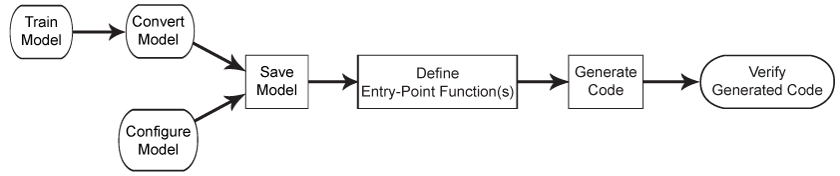

The flow chart suggests two distinct but merging workflows.

- The workflow beginning with **Train Model > Convert Model** requires data, in which case you can optionally perform feature selection or optimize the model by performing cross-validation before generating code for incremental learning. 

- The workflow beginning with **Configure Model** does not require data. Instead, you must manually configure an incremental learning model object.

For details on the differences between the workflows, and for help deciding which one to use, see [docid:stats_ug#mw_c4753575-71f7-4623-99c9-c480157b9f23](docid:stats_ug#mw_c4753575-71f7-4623-99c9-c480157b9f23).

Regardless of the workflow you choose, the resulting incremental learning model must have all the following qualities:

- The `NumPredictors` property reflect the number of predictors in the predictor data during incremental learning.

- For classification, the `ClassNames` property must contain all class names expected during incremental learning.

If you choose the **Train Model > Convert Model** workflow and you fit the model to data containing all known classes, the model is configured for code generation. 

After you prepare an incremental learning model, save the model object by using `saveLearnerForCoder`. Then, define an entry-point function that loads the saved model by using `loadLearnerForCoder`, and that performs incremental learning by calling the object functions. Alternatively, you can define multiple entry-point functions that perform the stages of incremental learning separately (this example uses this workflow). However, this workflow requires special treatment when an updated model object is an input to another entry-point function. For example, you write the following three entry-point functions: 

- A function that accepts the current model and a batch of data, calls [`updateMetrics`](docid:stats_ug#mw_c5db68b3-16a1-4b8b-90b9-7f3c76289dce), and returns a model with updated performance metrics.

- A function that accepts the updated model and the batch of data, calls [`fit`](docid:stats_ug#mw_665feb66-5ad1-4a02-8d42-32a1a738997c), and returns a model with updated coefficients. 

- A function that accepts the further updated model and the batch of predictor data, calls [`predict`](docid:stats_ug#mw_1d13a443-0b4a-44bb-a4df-c34b8a9ce1d5), and returns predicted labels.

Finally, generate code for the entry-point functions by using `codegen`, and verify the generated code. 

## Load and Preprocess Data

Load the human activity data set. Randomly shuffle the data.

idxTest

idxTest =     76    48    62    28    26    47    16    99    92   106    84   119


idxTestSort

idxTestSort =     16    26    28    47    48    62    76    84    92    99   106   119


idxTestAll

idxTestAll =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011


idxTestAll_batIndex

idxTestAll_batIndex =     16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16


unique(idxTestAll_batIndex)

ans =     16    26    28    47    48    62    76    84    92    99   106   119



idxTestAll_batIndex1 = (idxTestAll_batIndex == 16)

idxTestAll_batIndex1 = 1×4488 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


idxTestAll_test1 = idxTestAll(find(idxTestAll_batIndex == idxTest(7)))

idxTestAll_test1 =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011


idxTestAll_test1 = idxTestAll(find(idxTestAll_batIndex == idxTestSort(1)))

idxTestAll_test1 =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011



testBatNum = length(idxTestSort)

testBatNum = 12

size(idxTestSort)

ans =      1    12


findMaxFinal=0

findMaxFinal = 0

for i=1: testBatNum 
    temp = idxTestAll(find(idxTestAll_batIndex == idxTestSort(i)));
    findMax = length(temp);
    if findMax > findMaxFinal
        findMaxFinal = findMax;
    end
end
findMaxFinal

findMaxFinal = 1019

%TrainX = zeros(testBatNum,findMaxFinal,20);
%
% for i=1: 1 
%     tempIdx = idxTestAll(find(idxTestAll_batIndex == idxTestSort(i)));
%     temp = xnorm_Vd(tempIdx,:)
%     temp_len = length(temp);
%     temp_nan =  NaN((findMaxFinal-temp_len),20);
%     temp_new = [ temp ; temp_nan ] ;
%     TrainX(i,:,:) = temp_new
% end
% TrainX(:,:,1)

%xnorm_1  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(1 ))) , : )
% len = length(xnorm_2) 
% len_extra = mod(len,5)
% fixed_len = len -len_extra 

xnorm_1  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(1 ))) , : );
xnorm_2  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(2 ))) , : );
xnorm_3  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(3 ))) , : );
xnorm_4  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(4 ))) , : );
xnorm_5  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(5 ))) , : );
xnorm_6  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(6 ))) , : );
xnorm_7  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(7 ))) , : );
xnorm_8  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(8 ))) , : );
xnorm_9  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(9 ))) , : );
xnorm_10 =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(10))) , : );
xnorm_11 =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(11))) , : );
xnorm_12 =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(12))) , : );

ynorm_1  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(1 ))) );
ynorm_2  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(2 ))) );
ynorm_3  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(3 ))) );
ynorm_4  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(4 ))) );
ynorm_5  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(5 ))) );
ynorm_6  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(6 ))) );
ynorm_7  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(7 ))) );
ynorm_8  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(8 ))) );
ynorm_9  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(9 ))) );
ynorm_10 =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(10))) );
ynorm_11 =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(11))) );
ynorm_12 =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(12))) );

Y_1  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(1 ))) );
Y_2  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(2 ))) );
Y_3  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(3 ))) );
Y_4  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(4 ))) );
Y_5  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(5 ))) );
Y_6  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(6 ))) );
Y_7  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(7 ))) );
Y_8  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(8 ))) );
Y_9  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(9 ))) );
Y_10 =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(10))) );
Y_11 =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(11))) );
Y_12 =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(12))) );
	


len_1  =  length(xnorm_1 ) - mod(length(xnorm_1 ),5) ; 
len_2  =  length(xnorm_2 ) - mod(length(xnorm_2 ),5) ; 
len_3  =  length(xnorm_3 ) - mod(length(xnorm_3 ),5) ; 
len_4  =  length(xnorm_4 ) - mod(length(xnorm_4 ),5) ; 
len_5  =  length(xnorm_5 ) - mod(length(xnorm_5 ),5) ; 
len_6  =  length(xnorm_6 ) - mod(length(xnorm_6 ),5) ; 
len_7  =  length(xnorm_7 ) - mod(length(xnorm_7 ),5) ; 
len_8  =  length(xnorm_8 ) - mod(length(xnorm_8 ),5) ; 
len_9  =  length(xnorm_9 ) - mod(length(xnorm_9 ),5) ; 
len_10 =  length(xnorm_10) - mod(length(xnorm_10),5) ; 
len_11 =  length(xnorm_11) - mod(length(xnorm_11),5) ; 
len_12 =  length(xnorm_12) - mod(length(xnorm_12),5) ; 


xnorm_1  =  xnorm_1 (1:len_1  ,:);
xnorm_2  =  xnorm_2 (1:len_2  ,:);
xnorm_3  =  xnorm_3 (1:len_3  ,:);
xnorm_4  =  xnorm_4 (1:len_4  ,:);
xnorm_5  =  xnorm_5 (1:len_5  ,:);
xnorm_6  =  xnorm_6 (1:len_6  ,:);
xnorm_7  =  xnorm_7 (1:len_7  ,:);
xnorm_8  =  xnorm_8 (1:len_8  ,:);
xnorm_9  =  xnorm_9 (1:len_9  ,:);
xnorm_10 =  xnorm_10(1:len_10 ,:);
xnorm_11 =  xnorm_11(1:len_11 ,:);
xnorm_12 =  xnorm_12(1:len_12 ,:);

ynorm_1  =  ynorm_1 (1:len_1  ,:);
ynorm_2  =  ynorm_2 (1:len_2  ,:);
ynorm_3  =  ynorm_3 (1:len_3  ,:);
ynorm_4  =  ynorm_4 (1:len_4  ,:);
ynorm_5  =  ynorm_5 (1:len_5  ,:);
ynorm_6  =  ynorm_6 (1:len_6  ,:);
ynorm_7  =  ynorm_7 (1:len_7  ,:);
ynorm_8  =  ynorm_8 (1:len_8  ,:);
ynorm_9  =  ynorm_9 (1:len_9  ,:);
ynorm_10 =  ynorm_10(1:len_10 ,:);
ynorm_11 =  ynorm_11(1:len_11 ,:);
ynorm_12 =  ynorm_12(1:len_12 ,:);

Y_1  =  Y_1 (1:len_1  ,:);
Y_2  =  Y_2 (1:len_2  ,:);
Y_3  =  Y_3 (1:len_3  ,:);
Y_4  =  Y_4 (1:len_4  ,:);
Y_5  =  Y_5 (1:len_5  ,:);
Y_6  =  Y_6 (1:len_6  ,:);
Y_7  =  Y_7 (1:len_7  ,:);
Y_8  =  Y_8 (1:len_8  ,:);
Y_9  =  Y_9 (1:len_9  ,:);
Y_10 =  Y_10(1:len_10 ,:);
Y_11 =  Y_11(1:len_11 ,:);
Y_12 =  Y_12(1:len_12 ,:);


ryan4_util_gen_header(xnorm_1   ,ynorm_1   ,Y_1  ,1  )
ryan4_util_gen_header(xnorm_2   ,ynorm_2   ,Y_2  ,2  )
ryan4_util_gen_header(xnorm_3   ,ynorm_3   ,Y_3  ,3  )
ryan4_util_gen_header(xnorm_4   ,ynorm_4   ,Y_4  ,4  )
ryan4_util_gen_header(xnorm_5   ,ynorm_5   ,Y_5  ,5  )
ryan4_util_gen_header(xnorm_6   ,ynorm_6   ,Y_6  ,6  )
ryan4_util_gen_header(xnorm_7   ,ynorm_7   ,Y_7  ,7  )
ryan4_util_gen_header(xnorm_8   ,ynorm_8   ,Y_8  ,8  )
ryan4_util_gen_header(xnorm_9   ,ynorm_9   ,Y_9  ,9  )
ryan4_util_gen_header(xnorm_10  ,ynorm_10  ,Y_10 ,10 )
ryan4_util_gen_header(xnorm_11  ,ynorm_11  ,Y_11 ,11 )
ryan4_util_gen_header(xnorm_12  ,ynorm_12  ,Y_12 ,12 )

%  2520/8
% len = length(xnorm_1)
%     idx = 1
%     formatSpec_filename = 'xnorm_%d.h';
%     filename = num2str(idx,formatSpec_filename)
%     fid = fopen(filename,'w')
% 
%     formatSpec_variablename = 'double x_norm[%d][20] = { \n '
%     variablename = num2str(len,formatSpec_variablename)
%     fprintf(fid,variablename); 
%     for i=1:len 
%         str = num2str(xnorm_1(i,:));
%         str = regexprep(str,'\s+',',');
%         if i == len 
%             fprintf(fid,'  {%s}  } ; \n',str);
%         else
%             fprintf(fid,'  {%s} , \n',str);
%         end
%     end 
%     
%     fclose(fid);
% 
%    fid = fopen('xnorm.h','w');
%     %str = "double x_train[315][20] = ]n"
%     fprintf(fid,'double x_norm[315][20] = { \n');
%     for i=1:len 
%         str = num2str(Xtrain(i,:));
%         str = regexprep(str,'\s+',',');
%         if i == len 
%             fprintf(fid,'  {%s}  } ; \n',str);
%         else
%             fprintf(fid,'  {%s} , \n',str);
%         end
%     end 
%     fclose(fid);
%     
%     % https://kr.mathworks.com/matlabcentral/answers/448260-write-data-to-header-file
%     len = length(ynorm_1)
%     % https://en.cppreference.com/w/cpp/language/array
%     
%     fid = fopen('y_norm.h','w');
%     %str = "double x_train[315][20] = ]n"
%     fprintf(fid,'double y_norm[315][1] = { \n');
%     for i=1:len 
%         str = num2str(ytrain(i,:));
%         %str = regexprep(str,'\s+',',');
%         if i == len 
%             fprintf(fid,'  {%s}  } ; \n',str);
%         else
%             fprintf(fid,'  {%s} , \n',str);
%         end
%     end 
%     fclose(fid);
%     
%     fid = fopen('y.h','w');
%     %str = "double x_train[315][20] = ]n"
%     fprintf(fid,'double y[315][1] = { \n');
%     for i=1:len 
%         str = num2str(Y(i,:));
%         %str = regexprep(str,'\s+',',');
%         if i == len 
%             fprintf(fid,'  {%s}  } ; \n',str);
%         else
%             fprintf(fid,'  {%s} , \n',str);
%         end
%     end 
%     fclose(fid);


idxTest;
idxAll;

find(idxTestAll_batIndex == idxTest(7));
idxTestAll_test1 = idxTestAll(find(idxTestAll_batIndex == idxTest(7)));

RUL(idxTestAll_test1);
test_bat = idxTest(7);
RUL_test = RUL(idxTestAll(find(idxTestAll_batIndex == test_bat)));
ynorm_RUL_test = ynorm_RUL(idxTestAll(find(idxTestAll_batIndex == test_bat)));
SOH_test = Cap(idxTestAll(find(idxTestAll_batIndex == test_bat)));
ynorm_SOH_test = ynorm_SOH(idxTestAll(find(idxTestAll_batIndex == test_bat)));

Ic_test = Ic(idxTestAll(find(idxTestAll_batIndex == test_bat)),:);
Vd_test = Vd(idxTestAll(find(idxTestAll_batIndex == test_bat)),:);
xnorm_Vd_test = xnorm_Vd(idxTestAll(find(idxTestAll_batIndex == test_bat)),:);
ytrain = ynorm_RUL_test;
Xtrain = xnorm_Vd_test;
Ytrain = RUL_test;

idxSearch = 1; % 316
idxSearch2 = 2; % 239

idxFind = idxTest(find(idxTest == idxTestSort(idxSearch)));
idxFindAll = find(idxTestAll_batIndex == idxFind);
Y_test_RUL_test1 = Y_test_RUL(idxFindAll);
Y_test_SOH_test1 = Y_test_SOH(idxFindAll);


compareTo = Y_test_RUL_test1(1);

idx = idxTestSort(idxSearch); %16
% find most similar data
idxTrainValid = [idxTrain idxValid];

count = length(idxTrain) + length(idxValid);
idxSel = 0;
diff = 1000;
for i=1:count 
    diff_new = abs( ryan4_battery_dataset(idxTrainValid(i)).cycle_life - compareTo );
    if diff_new < diff 
        idxSel = idxTrainValid(i);
        diff = diff_new;
    end
end


matchedRUL = ryan4_battery_dataset(idxSel).cycle_life;
inTrain = any(idxTrain==idxSel);

if inTrain
    idxFindSel = idxTest(find(idxTest == idxTestSort(idxSearch)));
    idxFindAllSel = find(idxTestAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
else
    idxFindSel = idxTest(find(idxValid == idxValidSort(idxSearch)));
    idxFindAllSel = find(idxValidAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
end 


ytrainSim = y_test_RUL_Sel1;

figure, hold on
plot(ryan4_battery_dataset(idx).QDischargeSmooth)
plot(ryan4_battery_dataset(idxSel).QDischargeSmooth)
hold off



idxFind2 = idxTest(find(idxTest == idxTestSort(idxSearch2)));
idxFindAll2 = find(idxTestAll_batIndex == idxFind2);
Y_test_RUL_test2 = Y_test_RUL(idxFindAll2);
% Yfit_test_RUL_test2 = Yfit_test_RUL(idxFindAll2);


load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinear')
LinearMdl = mdl_Linear_VdRul_fitrlinear;

`Metrics` **—** **Model performance metrics to track during incremental learning**

`"classiferror"` (default) | function handle | cell vector | structure array

Model performance metrics to track during incremental learning with the [`updateMetrics`](https://www.mathworks.com/help/releases/R2022a/stats/incrementalclassificationecoc.updatemetrics.html) or [`updateMetricsAndFit`](https://www.mathworks.com/help/releases/R2022a/stats/incrementalclassificationecoc.updatemetricsandfit.html) function, specified as `"classiferror"` ([classification error](https://www.mathworks.com/help/releases/R2022a/stats/classificationecoc.incrementallearner.html#mw_8fb753e8-05af-4a54-87db-7942764683c7_sep_shared-ClassificationError), or misclassification error rate), a function handle (for example, `@metricName`), a structure array of function handles, or a cell vector of names, function handles, or structure arrays.

To specify a custom function that returns a performance metric, use function handle notation. The function must have this form.

`metric = customMetric(C,S)`

- The output argument `metric` is an *n*-by-1 numeric vector, where each element is the loss of the corresponding observation in the data processed by the incremental learning functions during a learning cycle.

- You specify the function name (here, `customMetric`).

- `C` is an *n*-by-*K* logical matrix with rows indicating the class to which the corresponding observation belongs, where *K* is the number of classes. The column order corresponds to the class order in the `ClassNames` property. Create `C` by setting `C(``p``,``q``)` = `1`, if observation `p` is in class `q`, for each observation in the specified data. Set the other element in row `p` to `0`.

- `S` is an *n*-by-*K* numeric matrix of predicted classification scores. `S` is similar to the `NegLoss` output of [`predict`](https://www.mathworks.com/help/releases/R2022a/stats/incrementalclassificationecoc.predict.html), where rows correspond to observations in the data and the column order corresponds to the class order in the `ClassNames` property. `S(``p``,``q``)` is the classification score of observation `p` being classified in class `q`.

To specify multiple custom metrics and assign a custom name to each, use a structure array. To specify a combination of built-in and custom metrics, use a cell vector.

`updateMetrics` and `updateMetricsAndFit` store specified metrics in a table in the [`Metrics`](https://www.mathworks.com/help/releases/R2022a/stats/incrementalclassificationecoc.html#mw_d0011a91-b04d-4865-b03c-435eaf011563_sep_shared-incrementallearner_metrics_prop) property. The data type of `Metrics` determines the row names of the table.

`Metrics` **Value Data Type****Description of** `Metrics` **Property Row Name****Example**

String or character vectorName of corresponding built-in metricRow name for `"classiferror"` is `"ClassificationError"`

Structure arrayField nameRow name for `struct(Metric1=@customMetric1)` is `"Metric1"`

Function handle to function stored in a program fileName of functionRow name for `@customMetric` is `"customMetric"`

Anonymous function`CustomMetric_``j`, where `j` is metric `j` in `Metrics`Row name for `@(C,S)customMetric(C,S)...` is `CustomMetric_1`

For more details on performance metrics options, see [Performance Metrics](https://www.mathworks.com/help/releases/R2022a/stats/classificationecoc.incrementallearner.html#mw_8fb753e8-05af-4a54-87db-7942764683c7_sep_shared-incrementallearner_metrics_algo_head).

**Example:** `Metrics=struct(Metric1=@customMetric1,Metric2=@customMetric2)`

**Example:** `Metrics={@customMetric1,@customMetric2,"classiferror",struct(Metric3=@customMetric3)}`

**Data Types:** `char` | `string` | `struct` | `cell` | `function_handle`

[https://kr.mathworks.com/matlabcentral/answers/629998-how-to-save-loss-rmse-mae-and-mape-in-every-training-epoch](https://kr.mathworks.com/matlabcentral/answers/629998-how-to-save-loss-rmse-mae-and-mape-in-every-training-epoch)

Is there any suggestion on how to save the loss, rmse, mae, and mape in every training epoch? I want to compare them in condition of different parameters later.

Cheers

FYI I calculate the rmse, mae, and mape in the end like this:

ThemeCopy

`net = trainNetwork(XTrain,YTrain,layers,options);`

`net = predictAndUpdateState(net,XTrain);`

`[net,YPred] = predictAndUpdateState(net,XTest);`

`YPred = sig(1)*YPred + mu(1);`

`YTest = dataTest(1,:);`

`rmse = sqrt(mean((YPred-YTest).^2))`

`mae = mean(abs(YPred-YTest))`

`mape = mean(abs((YPred-YTest)./YTest))*100`

rmsefcn = @(z,zfit)sqrt(mean((z - zfit).^2));
msefcn = @(z,zfit)mean((z - zfit).^2);
maefcn = @(z,zfit)abs(z - zfit);
mapefcn = @(z,zfit)mean(abs(z - zfit)/z)*100;

Metrics={'mse'}

Metrics = 1×1 cell array
    {'mse'}


%Metrics={'mse',struct(MeanAbsoluteError=@myMAE),struct(RootMeanSquareError=@myRMSE),struct(MeanAbsolutePercentageError=@myMAPE)}
% Metrics={"mse",struct(RootMeanSquarError=@rmsefcn),struct(MeanAbsoluteError=@maefcn),struct(MeanAbsolutePercentiageError=@mapefcn)}

maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

`Metrics={"mse",struct(MeanAbsoluteError=@maefcn)}`

`??? Undefined function or variable 'maefcn'.`

`Error in ==> `[`incrementalRegressionLinear Line: 187 Column: 43`](matlab: emlcprivate('emcopentoline','C:\Program Files\MATLAB\R2022a\toolbox\stats\incremental\+incremental\+coder\incrementalRegressionLinear.m',187,43);)

`Code generation failed: `[`View Error Report`](matlab: open('C:\nobackup\_phd_work\_battery_soh\_matlab_battery\_mywork\_latest\codegen\mex\myIncrLearn_mex\html\report.mldatx');)



n = numel(ytrain);
IncrementalMdl = incrementalLearner(LinearMdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',Metrics ...
    )

IncrementalMdl =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


    % 'Metrics',{ 'mse'  maemetric }...

LinearMdl

LinearMdl =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


## Configure Incremental Learning Model

To generate code for incremental classification, you must appropriately configure a binary classification linear model for incremental learning `incrementalClassificationLinear`. 

Create a binary classification (SVM) model for incremental learning.  Fully configure the model for code generation by specify all expected class names and the number of predictor variables. Also, specify tracking the misclassification rate and hinge loss. For reproducibility, this example turns off observation shuffling for the scale-invariant solver.

% metrics = ["classiferror" "hinge"];
% IncrementalMdl = incrementalClassificationLinear('ClassNames',classnames,'NumPredictors',p,...
%     'Shuffle',false,'Metrics',metrics)

`Mdl` is an `incremenalClassificationLinear` model object configured for code generation. `Mdl` is *cold* (`Mdl.IsWarm` is `0`) because it has not processed data—the coefficients are `0`.

Alternatively, because the data is available, you can fit an SVM model to the data by using either `fitcsvm` or `fitclinear`, and then convert the resulting model to an incremental learning model by passing the model to `incrementalLearner`. The resulting model is *warm* because it has processed data—its coefficients are likely non-zero.

## Save Model Using `saveLearnerForCoder`

Save the incremental learning model to the file `InitialMdl.mat` by using [`saveLearnerForCoder`](docid:stats_ug.bvclu99). 

% saveLearnerForCoder(IncrementalMdl,'InitialMdl');
saveLearnerForCoder(IncrementalMdl,'InitialMdl');
saveLearnerForCoder(LinearMdl,'InitialLinearMdl');

`saveLearnerForCoder` saves the incremental learning model to the MATLAB binary file `SVMClassIncrLearner.mat` as structure arrays in the current folder.

## Define Entry-Point Functions

An *entry-point* function, also known as the *top-level* or *primary* function, is a function you define for code generation. Because you cannot call any function at the top level using `codegen`, you must define an entry-point function that calls code-generation-enabled functions, and generate C/C++ code for the entry-point function by using `codegen`. All functions within the entry-point function must support code generation.

Define four separate entry-point functions in your current folder that perform the following actions:

- `myInitialModelIncrLearn.m` — Load the saved model by using [`loadLearnerForCoder`](docid:stats_ug.bvcl05n-1), and return a model of the same form for code generation. This entry-point function facilitates the use of a model, returned by an entry-point function, as an input to another entry-point function.

- `myUpdateMetricsIncrLearn.m` — Measure the performance of the current model on an incoming batch of data, and store the performance metrics in the model. The function accepts the current model, and predictor and response data, and returns an updated model.

- `myFitIncrLearn.m` — Fit the current model to the incoming batch of data, and store the updated coefficients in the model. The function accepts the current model, and predictor and response data, and returns an updated model. 

- `myPredictIncrLearn.m` — Predicted labels for the incoming batch of data using the current model. The function accepts the current model and predictor data, and returns labels and class scores.

For more details on generating code for multiple entry-point functions, see [docid:coder_ug#bsd8i4b-1](docid:coder_ug#bsd8i4b-1).

Add the `%#codegen` compiler directive (or pragma) to the entry-point function after the function signature to indicate that you intend to generate code for the MATLAB algorithm. Adding this directive instructs the MATLAB Code Analyzer to help you diagnose and fix violations that would result in errors during code generation. See [Check Code with the Code Analyzer](docid:coder_ug.btln3cg).

Alternatively, you can access the functions in `mlr/examples/stats/main`, where `mlr` is the value of `matlabroot`.

Display the body of each function.

type myInitialModelIncrLearn.m
type myInitialModelLearn.m
type myUpdateMetricsIncrLearn.m
type myUpdateMetricsAndFitIncrLearn.m
type myFitIncrLearn.m
type myPredictIncrLearn.m

## Generate Code

**Set Up Compiler**

To generate C/C++ code, you must have access to a C/C++ compiler that is configured properly. MATLAB Coder locates and uses a supported, installed compiler. You can use `mex` `-setup` to view and change the default compiler. For more details, see [Change Default Compiler](docid:matlab_external.btw3qmj).

**Build Type**

MATLAB Coder can generate code for the following build types: 

- MEX (MATLAB Executable) function

- Standalone C/C++ code

- Standalone C/C++ code compiled to a static library

- Standalone C/C++ code compiled to a dynamically linked library

- Standalone C/C++ code compiled to an executable

You can specify the build type using the `-config` option of [`codegen`](docid:coder_ref.br46oyi-1). For more details on setting code generation options, see the `-config` option of [`codegen`](docid:coder_ref.br46oyi-1) and [Configure Build Settings](docid:coder_ug.bsw7_wl).

By default, `codegen` generates a MEX function. A MEX function is a C/C++ program that is executable from MATLAB. You can use a MEX function to accelerate MATLAB algorithms and to test the generated code for functionality and run-time issues. For details, see [MATLAB Algorithm Acceleration](docid:coder_doccenter#bs2r9v8-1) and [Why Test MEX Functions in MATLAB?](docid:coder_ug#bu7q816-1).

**Generate Code Using **`codegen`

Because C and C++ are statically typed languages, you must specify the properties of all variables in the entry-point function at compile time. Specify the following:

- The data types of the data inputs of the entry-point functions by using [`coder.typeof`](docid:coder_ref.bsu_35x). Also, because the number of observations can vary from batch to batch, specify that the number of observations (first dimension) has variable size. For details, see [Specify Variable Sized Arguments for Code Generation](docid:stats_ug.bvnu22q) and [Specify Properties of Entry-Point Function Inputs](docid:coder_ug.bq9_nbz).

- Because several entry-point functions accept an incremental model object as a input, and operate on it, create a representation of the model object for code generation by using [`coder.OutputType`](docid:coder_ref#mw_186147ed-8160-4651-9402-66b666c36a83). For more details, see [docid:coder_ug#mw_3673faa4-a8d2-472f-a7a6-28989f410538](docid:coder_ug#mw_3673faa4-a8d2-472f-a7a6-28989f410538).

% predictorData = coder.typeof(X,[],[true false]); 
% responseData = coder.typeof(Y,[],true);
% IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% predictorData = coder.typeof(ones(5,20)); %coder.typeof(Xtrain); 
% responseData = coder.typeof(ones(5));  ^coder.typeof(ytrain);

predictorData = coder.typeof(Xtrain(1:5,:)); 

function incrementalModel = myInitialModelIncrLearn() %#codegen
% MYINITIALMODELINCRLEARN Load and return configured linear model for
% binary classification InitialMdl
    incrementalModel = loadLearnerForCoder('scenario_6_Mdl');
end


responseData = coder.typeof(ytrain(1:5));

function linearModel = myInitialModelLearn() %#codegen
% MYINITIALMODELINCRLEARN Load and return configured linear model for
% binary classification InitialMdl
    linearModel = loadLearnerForCoder('InitialLinearMdl');
end


observedData = coder.typeof(ytrain(1:5));

function incrementalModel = myUpdateMetricsIncrLearn(incrementalModel,X,Y) %#codegen
% MYUPDATEMETRICSINCRLEARN Measure model performance metrics on new data
      incrementalModel = updateMetrics(incrementalModel,X,Y); 
end


IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

function incrementalModel = myUpdateMetricsAndFitIncrLearn(incrementalModel,X,Y) %#codegen
% MYUPDATEMETRICSINCRLEARN Measure model performance metrics on new data
      incrementalModel = updateMetricsAndFit(incrementalModel,X,Y); 
end


LinearMdlOutputType = coder.OutputType('myInitialModelLearn');

function incrementalModel = myFitIncrLearn(incrementalModel,X,Y) %#codegen
% MYFITINCRLEARN Fit model to new data
      incrementalModel = fit(incrementalModel,X,Y); 
end


function [labels] = myPredictIncrLearn(incrementalModel,X) %#codegen
% MYPREDICTINCRLEARN Predict labels and classification scores on new data
      [labels] = predict(incrementalModel,X); 
end


Xtrain = Xtrain(1:315,:);
ytrain = ytrain(1:315,:);
Ytrain = Ytrain(1:315,:);


writematrix(Xtrain,'x_norm.csv') 
writematrix(ytrain,'y_norm.csv') 
writematrix(ytrain,'y.csv') 

% https://kr.mathworks.com/matlabcentral/answers/448260-write-data-to-header-file
len = length(Xtrain)
% https://en.cppreference.com/w/cpp/language/array

fid = fopen('x_norm.h','w');
%str = "double x_train[315][20] = ]n"
fprintf(fid,'double x_norm[315][20] = { \n');
for i=1:len 
    str = num2str(Xtrain(i,:));
    str = regexprep(str,'\s+',',');
    if i == len 

len = 315

        fprintf(fid,'  {%s}  } ; \n',str);
    else
        fprintf(fid,'  {%s} , \n',str);
    end
end 
fclose(fid);

% https://kr.mathworks.com/matlabcentral/answers/448260-write-data-to-header-file
len = length(ytrain)
% https://en.cppreference.com/w/cpp/language/array

fid = fopen('y_norm.h','w');
%str = "double x_train[315][20] = ]n"
fprintf(fid,'double y_norm[315][1] = { \n');
for i=1:len 
    str = num2str(ytrain(i,:));
    %str = regexprep(str,'\s+',',');
    if i == len 

len = 315

        fprintf(fid,'  {%s}  } ; \n',str);
    else
        fprintf(fid,'  {%s} , \n',str);
    end
end 
fclose(fid);

fid = fopen('y.h','w');
%str = "double x_train[315][20] = ]n"
fprintf(fid,'double y[315][1] = { \n');
for i=1:len 
    str = num2str(Ytrain(i,:));
    %str = regexprep(str,'\s+',',');
    if i == len 
        fprintf(fid,'  {%s}  } ; \n',str);
    else
        fprintf(fid,'  {%s} , \n',str);
    end
end 
fclose(fid);


% str = regexprep(str,'\s+',',');
% % Save as 'sample.h' file
% fid = fopen('sample.h','w');
% fprintf(fid,'sineTable[800] = {%s};\n',str);
% fclose(fid);

cfg = coder.config('lib','ecoder',false);
cfg.GenCodeOnly = true;
cfg.HardwareImplementation.ProdHWDeviceType = 'ARM Compatible->ARM Cortex';


% https://kr.mathworks.com/help/stats/classreg.learning.coder.config.linear.regressionlinearcoderconfigurer.html
Xtrain_one_sample = Xtrain(1,:)
%configurer = learnerCoderConfigurer(LinearMdl,Xtrain_one_sample,'ObservationsIn','columns')
configurer = learnerCoderConfigurer(LinearMdl,Xtrain_one_sample) %,'ObservationsIn','columns')

configurer.OutputFileName
configurer.UpdateInputs


generateCode(configurer,cfg)

Xtrain_one_sample =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011



type predict.m

configurer =   RegressionLinearCoderConfigurer with properties:

   Update Inputs:
              Beta: [1×1 LearnerCoderInput]
              Bias: [1×1 LearnerCoderInput]

   Predict Inputs:
                 X: [1×1 LearnerCoderInput]

   Code Generation Parameters:
        NumOutputs: 1
    OutputFileName: 'RegressionLinearModel'


  Properties, Methods


type update.m
type initialize.m

ans = 'RegressionLinearModel'

myBuildInfoFile = 'codegen/lib/RegressionLinearModel/buildInfo.mat';

ans = 1×1 cell array
    {1×1 struct}


load(myBuildInfoFile);
packNGo(buildInfo);

% Verify code.

generateCode creates these files in output folder:
'initialize.m', 'predict.m', 'update.m', 'RegressionLinearModel.mat'
Code generation successful.



y_out = predict(LinearMdl,Xtrain_one_sample)
ytrain(1)

function varargout = predict(X,varargin) %#codegen
% Autogenerated by MATLAB, 09-Jun-2022 10:15:42
[varargout{1:nargout}] = initialize('predict',X,varargin{:});
end


Ytrain(1)

function update(varargin) %#codegen
% Autogenerated by MATLAB, 09-Jun-2022 10:15:42
initialize('update',varargin{:});
end


xrate_Vd_RUL

function [varargout] = initialize(command,varargin) %#codegen
% Autogenerated by MATLAB, 09-Jun-2022 10:15:42
coder.inline('always')
persistent model
if isempty(model)
    model = loadLearnerForCoder('RegressionLinearModel.mat');
end
switch(command)
    case 'update'
        % Update struct fields: Beta
        %                       Bias
        model = update(model,varargin{:});
    case 'predict'
        % Predict Inputs: X
        X = varargin{1};
        if nargin == 2
            [varargout{1:nargout}] = predict(model,X);
        else
            PVPairs = cell(1,nargin-2);
            for i = 1:nargin-2
                PVPairs{1,i} = varargin{i+1};
            end
            [varargout{1:nargout}] = predict(model,X,PVPairs{:});
        end
end
end


xmin_Vd_RUL
yrate_RUL
ymin_RUL

Yfit_out = y_out * yrate_RUL + ymin_RUL
% 라즈베리 파이에서 잘 동작한다.
% here

y_out = 0.3864

length(xnorm_Vd_test) 

ans = 0.2692

yfit_test_VdRul_fitrlinear = predict(LinearMdl,Xtrain);

ans = 316

yfit_test_VdRul_fitrlinear

xrate_Vd_RUL = 1.3307

Yfit_test_VdRul_fitrlinear = yfit_test_VdRul_fitrlinear.*yrate_RUL + ymin_RUL

xmin_Vd_RUL = 1.9987

AE = abs(Ytrain - Yfit_test_VdRul_fitrlinear )

yrate_RUL = 1170

APE = AE./Ytrain

ymin_RUL = 1

MAPE = sum(APE)/length(APE)*100
RMSE = sqrt(sum(AE.^2)/length(AE))

Yfit_out = 453.0394

%[result_mdl_Linear_VdRul_fitrlinear,result_mdl_Linear_VdRul_fitrlinear_summary] = ...
  %  ryan4_util_linear(yfit_trainValid_VdRul_fitrlinear,yfit_test_VdRul_fitrlinear,yrate_RUL,ymin_RUL,...
   % Y_trainValid_RUL,Y_test_RUL)

ans = 316

Generate code for the entry-point functions using [`codegen`](docid:coder_ref.br46oyi-1).  For each entry-point function argument, use the `-args` flags to specify the coder representations of the variables. Specify the output MEX function name `myIncrLearn_mex`. 

 codegen -config cfg  ...
 myInitialModelIncrLearn ... 

yfit_test_VdRul_fitrlinear =     0.3864
    0.3818
    0.3792
    0.3758
    0.3734
    0.3723
    0.3706
    0.3700
    0.3668
    0.3643


 myMAE –args {observedData,responseData} ...

Yfit_test_VdRul_fitrlinear =   453.0394
  447.6817
  444.6999
  440.6494
  437.8507
  436.5329
  434.6521
  433.8654
  430.2006
  427.1951


 myRMSE –args {observedData,responseData} ...

AE =   137.0394
  132.6817
  130.6999
  127.6494
  125.8507
  125.5329
  124.6521
  124.8654
  122.2006
  120.1951


 myMAPE –args {observedData,responseData} ...

APE =     0.4337
    0.4212
    0.4162
    0.4078
    0.4034
    0.4036
    0.4021
    0.4041
    0.3968
    0.3915


 myMSE –args {observedData,responseData} ...

MAPE = 32.7476

 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...

RMSE = 56.3081

 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report

 % myInitialModelLearn
%   initialize -args ARGS ... 
%  update -args ARGS ...
%  predict -args ARGS ... 

For help debugging code generation issues, view the generated C/C++ code by clicking `View report` (see [Code Generation Reports](docid:coder_ug.brbmkp4-1)).

Code generation successful: View report



myBuildInfoFile = 'codegen/lib/myInitialModelIncrLearn/buildInfo.mat';
load(myBuildInfoFile);
packNGo(buildInfo);

## Verify Generated Code

Test the MEX function to verify that the generated code provides the same functionality as the original MATLAB code. To perform this test, run the MEX function using the same inputs that you used to run the original MATLAB code, and then compare the results. Running the MEX function in MATLAB before generating standalone code also enables you to detect and fix run-time errors that are much harder to diagnose in the generated standalone code. For more details, see [Why Test MEX Functions in MATLAB?](docid:coder_ug#bu7q816-1).

Perform incremental learning by using the generated MEX functions and directly by using the object functions. Specify a batch 

% % Preallocation
% numObsPerChunk = 50;
% nchunk = floor(n/numObsPerChunk);
% ce = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% hinge = ce;
% ceCG = ce;
% hingeCG = ce;
% IncrementalMdlCG = myIncrLearn_mex('myInitialModelIncrLearn');
% scores = zeros(n,2);
% scoresCG = zeros(n,2);
% 
% % Incremental fitting
% for j = 1:nchunk
%     ibegin = min(n,numObsPerChunk*(j-1) + 1);
%     iend   = min(n,numObsPerChunk*j);
%     idx = ibegin:iend;
% 
%     IncrementalMdl = updateMetrics(IncrementalMdl,X(idx,:),Y(idx));
%     ce{j,:} = IncrementalMdl.Metrics{"ClassificationError",:};
%     hinge{j,:} = IncrementalMdl.Metrics{"HingeLoss",:};
%     IncrementalMdlCG = myIncrLearn_mex('myUpdateMetricsIncrLearn',IncrementalMdlCG,...
%         X(idx,:),Y(idx));
%     ceCG{j,:} = IncrementalMdlCG.Metrics{"ClassificationError",:};
%     hingeCG{j,:} = IncrementalMdlCG.Metrics{"HingeLoss",:};
% 
%     IncrementalMdl = fit(IncrementalMdl,X(idx,:),Y(idx));
%     IncrementalMdlCG = myIncrLearn_mex('myFitIncrLearn',IncrementalMdlCG,X(idx,:),Y(idx));
%     
%     [~,scores(idx,:)] = predict(IncrementalMdl,X(idx,:));
%     [~,scoresCG(idx,:)] = myIncrLearn_mex('myPredictIncrLearn',IncrementalMdlCG,X(idx,:));
% end

% use when you need to debug
n = numel(ytrain);
IncrementalMdl = incrementalLearner(LinearMdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',Metrics ...
    )

IncrementalMdl =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods



IncrementalMdl.Beta'

ans =    -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0924   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


%%%%%%%%%%%%%%%%%%%%%
n = numel(ytrain);

% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);

IncrementalMdlCG = myIncrLearn_mex('myInitialModelIncrLearn');

ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    

ei_CG = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val_CG = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mae_CG = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10_CG = zeros(nchunk,1);    


y_predict = []; %zeros();
y_predict_CG = [];

% Incremental fitting
rng("default"); % For reproducibility
IncrementalMdl.Beta' 

ans =    -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0924   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


IncrementalMdlCG.Beta'

ans =    -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0924   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


IncrementalMdl.IsWarm

ans = logical
   0


for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend   ;
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    IncrementalMdl = updateMetricsAndFit(...
        IncrementalMdl,...
        Xtrain(idx,:),...
        ytrain(idx));
    IncrementalMdl.IsWarm 
    IncrementalMdl.Beta'
    IncrementalMdl.Bias
    IncrementalMdl.FitBias

    
    IncrementalMdlCG = myIncrLearn_mex('myUpdateMetricsAndFitIncrLearn', ... 
        IncrementalMdlCG,...
        Xtrain(idx,:),...
        ytrain(idx));

    y_predict_temp = predict(IncrementalMdl,Xtrain(idx,:));

    y_predict_temp_CG = myIncrLearn_mex('myPredictIncrLearn',IncrementalMdlCG,Xtrain(idx,:)); 

    IncrementalMdl.Beta';
    y_predict = [ y_predict ; y_predict_temp ];
    y_predict_CG = [ y_predict_CG ; y_predict_temp_CG ];

    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp];
    [ytrain(idx) y_predict_temp_CG ytrain(idx)-y_predict_temp_CG];

    %ei{j,:} = IncrementalMdl.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = IncrementalMdl.Metrics{"MeanSquaredError",:};
    beta10(j + 1) = IncrementalMdl.Beta(10);
    %mae{j,:} = IncrementalMdl.Metrics{"MeanAbsoluteError",:};

    mse_val_CG{j,:} = IncrementalMdlCG.Metrics{"MeanSquaredError",:};
    beta10_CG(j + 1) = IncrementalMdlCG.Beta(10);
    %mae_CG{j,:} = IncrementalMdlCG.Metrics{"MeanAbsoluteError",:};

    IncrementalMdlCG.Metrics
    [ IncrementalMdlCG.Metrics{"MeanSquaredError",:} IncrementalMdlCG.Beta(10)]
    
%     ceCG{j,:} = IncrementalMdlCG.Metrics{"ClassificationError",:};
%     hingeCG{j,:} = IncrementalMdlCG.Metrics{"HingeLoss",:};
end

ans = logical
   0


ans =    -0.4402   -0.2569   -0.0662    0.0264    0.1518    0.3210    0.4856    0.5569    0.4484    0.2338    0.0415   -0.1009   -0.0854   -0.0113    0.1326   -0.0375    1.0292    0.2708   -0.4946   -0.4823


ans = -1.0799

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2338


ans = logical
   0


ans =    -0.4383   -0.2551   -0.0644    0.0281    0.1535    0.3227    0.4872    0.5585    0.4500    0.2354    0.0431   -0.0994   -0.0839   -0.0099    0.1338   -0.0365    1.0295    0.2708   -0.4946   -0.4823


ans = -1.0779

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2354


ans = logical
   0


ans =    -0.4385   -0.2553   -0.0646    0.0279    0.1533    0.3225    0.4870    0.5583    0.4498    0.2352    0.0429   -0.0995   -0.0841   -0.0100    0.1337   -0.0366    1.0294    0.2708   -0.4945   -0.4822


ans = -1.0781

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2352


ans = logical
   0


ans =    -0.4375   -0.2544   -0.0637    0.0288    0.1541    0.3233    0.4877    0.5591    0.4505    0.2359    0.0437   -0.0988   -0.0833   -0.0094    0.1343   -0.0361    1.0295    0.2708   -0.4945   -0.4822


ans = -1.0771

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2359


ans = logical
   0


ans =    -0.4404   -0.2572   -0.0665    0.0260    0.1514    0.3206    0.4850    0.5564    0.4479    0.2334    0.0412   -0.1012   -0.0857   -0.0116    0.1322   -0.0377    1.0286    0.2707   -0.4944   -0.4821


ans = -1.0803

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2334


ans = logical
   0


ans =    -0.4405   -0.2572   -0.0666    0.0259    0.1513    0.3204    0.4849    0.5562    0.4477    0.2332    0.0411   -0.1013   -0.0858   -0.0117    0.1321   -0.0378    1.0285    0.2707   -0.4944   -0.4821


ans = -1.0804

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2332


ans = logical
   0


ans =    -0.4365   -0.2534   -0.0628    0.0296    0.1549    0.3240    0.4884    0.5597    0.4512    0.2367    0.0445   -0.0980   -0.0826   -0.0087    0.1349   -0.0357    1.0292    0.2707   -0.4943   -0.4820


ans = -1.0761

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2367


ans = logical
   0


ans =    -0.4366   -0.2536   -0.0630    0.0295    0.1547    0.3238    0.4882    0.5595    0.4510    0.2365    0.0443   -0.0981   -0.0827   -0.0088    0.1347   -0.0358    1.0290    0.2707   -0.4943   -0.4820


ans = -1.0763

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2365


ans = logical
   0


ans =    -0.4363   -0.2533   -0.0628    0.0297    0.1549    0.3240    0.4884    0.5596    0.4511    0.2367    0.0445   -0.0979   -0.0825   -0.0086    0.1349   -0.0356    1.0290    0.2706   -0.4942   -0.4819


ans = -1.0760

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2367


ans = logical
   1


ans =    -0.4362   -0.2532   -0.0627    0.0298    0.1550    0.3241    0.4884    0.5597    0.4512    0.2367    0.0446   -0.0978   -0.0824   -0.0086    0.1349   -0.0356    1.0289    0.2706   -0.4942   -0.4819


ans = -1.0759

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError       NaN         NaN  


ans =        NaN       NaN    0.2367


ans = logical
   1


ans =    -0.4376   -0.2546   -0.0641    0.0284    0.1536    0.3227    0.4870    0.5583    0.4498    0.2354    0.0433   -0.0991   -0.0836   -0.0097    0.1339   -0.0364    1.0285    0.2706   -0.4941   -0.4818


ans = -1.0775

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError    0.00026787     NaN  


ans =     0.0003       NaN    0.2354


ans = logical
   1


ans = 1×20
   -0.4357   -0.2527   -0.0622    0.0302    0.1554    0.3244    0.4887    0.5600    0.4515    0.2371    0.0450   -0.0974   -0.0821   -0.0082    0.1352   -0.0354    1.0287    0.2705   -0.4941   -0.4818


ans = -1.0754

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError    0.00044501     NaN  


ans = 1×3
    0.0004       NaN    0.2371


ans = logical
   1


ans = 1×20
   -0.4342   -0.2513   -0.0609    0.0315    0.1567    0.3257    0.4900    0.5612    0.4527    0.2383    0.0462   -0.0962   -0.0809   -0.0071    0.1362   -0.0346    1.0288    0.2705   -0.4940   -0.4817


ans = -1.0739

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError    0.00038014     NaN  


ans = 1×3
    0.0004       NaN    0.2383


ans = logical
   1


ans = 1×20
   -0.4335   -0.2507   -0.0602    0.0321    0.1573    0.3263    0.4905    0.5617    0.4533    0.2389    0.0468   -0.0957   -0.0804   -0.0066    0.1366   -0.0343    1.0288    0.2705   -0.4940   -0.4817


ans = -1.0731

ans = logical
   1


ans = 1×2 table
                        Cumulative    Window
                        __________    ______

    MeanSquaredError    0.0002999      NaN  


ans = 1×3
    0.0003       NaN    0.2389


ans = logical
   1


ans = 1×20
   -0.4330   -0.2502   -0.0598    0.0325    0.1577    0.3266    0.4909    0.5621    0.4536    0.2392    0.0471   -0.0953   -0.0800   -0.0063    0.1369   -0.0340    1.0287    0.2705   -0.4939   -0.4816


ans = -1.0727

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00024481    0.00024481


ans = 1×3
    0.0002    0.0002    0.2392


ans = logical
   1


ans = 1×20
   -0.4326   -0.2499   -0.0595    0.0329    0.1580    0.3269    0.4912    0.5623    0.4539    0.2395    0.0474   -0.0950   -0.0797   -0.0060    0.1371   -0.0339    1.0287    0.2704   -0.4939   -0.4816


ans = -1.0723

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00020768    0.00024481


ans = 1×3
    0.0002    0.0002    0.2395


ans = logical
   1


ans = 1×20
   -0.4321   -0.2495   -0.0591    0.0332    0.1584    0.3273    0.4915    0.5626    0.4542    0.2398    0.0478   -0.0947   -0.0794   -0.0057    0.1373   -0.0337    1.0286    0.2704   -0.4938   -0.4815


ans = -1.0718

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00018269    0.00024481


ans = 1×3
    0.0002    0.0002    0.2398


ans = logical
   1


ans = 1×20
   -0.4314   -0.2488   -0.0584    0.0339    0.1590    0.3279    0.4920    0.5632    0.4547    0.2404    0.0483   -0.0941   -0.0788   -0.0052    0.1378   -0.0333    1.0286    0.2704   -0.4938   -0.4815


ans = -1.0711

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00016778    0.00024481


ans = 1×3
    0.0002    0.0002    0.2404


ans = logical
   1


ans = 1×20
   -0.4300   -0.2475   -0.0572    0.0351    0.1602    0.3290    0.4932    0.5643    0.4558    0.2415    0.0494   -0.0930   -0.0778   -0.0042    0.1386   -0.0327    1.0286    0.2704   -0.4937   -0.4815


ans = -1.0697

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00017608    0.00024481


ans = 1×3
    0.0002    0.0002    0.2415


ans = logical
   1


ans = 1×20
   -0.4289   -0.2464   -0.0562    0.0361    0.1612    0.3300    0.4941    0.5652    0.4568    0.2424    0.0504   -0.0921   -0.0769   -0.0034    0.1393   -0.0322    1.0285    0.2703   -0.4937   -0.4814


ans = -1.0685

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00017297    0.00010112


ans = 1×3
    0.0002    0.0001    0.2424


ans = logical
   1


ans = 1×20
   -0.4287   -0.2463   -0.0560    0.0362    0.1613    0.3301    0.4942    0.5653    0.4568    0.2425    0.0505   -0.0919   -0.0768   -0.0033    0.1394   -0.0322    1.0284    0.2703   -0.4936   -0.4814


ans = -1.0683

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00015803    0.00010112


ans = 1×3
    0.0002    0.0001    0.2425


ans = logical
   1


ans = 1×20
   -0.4282   -0.2458   -0.0556    0.0366    0.1617    0.3305    0.4945    0.5656    0.4572    0.2429    0.0508   -0.0916   -0.0764   -0.0030    0.1397   -0.0320    1.0284    0.2703   -0.4936   -0.4813


ans = -1.0679

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00014694    0.00010112


ans = 1×3
    0.0001    0.0001    0.2429


ans = logical
   1


ans = 1×20
   -0.4277   -0.2453   -0.0551    0.0371    0.1621    0.3309    0.4950    0.5660    0.4576    0.2433    0.0513   -0.0911   -0.0760   -0.0026    0.1400   -0.0317    1.0283    0.2703   -0.4935   -0.4813


ans = -1.0673

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00014082    0.00010112


ans = 1×3
    0.0001    0.0001    0.2433


ans = logical
   1


ans = 1×20
   -0.4261   -0.2439   -0.0537    0.0385    0.1635    0.3322    0.4963    0.5673    0.4589    0.2446    0.0525   -0.0899   -0.0748   -0.0015    0.1409   -0.0311    1.0282    0.2702   -0.4935   -0.4812


ans = -1.0657

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00015058    0.00010112


ans = 1×3
    0.0002    0.0001    0.2446


ans = logical
   1


ans = 1×20
   -0.4259   -0.2436   -0.0535    0.0387    0.1637    0.3324    0.4964    0.5674    0.4590    0.2447    0.0527   -0.0897   -0.0747   -0.0014    0.1410   -0.0311    1.0281    0.2702   -0.4934   -0.4812


ans = -1.0655

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00014092    7.6821e-05


ans = 1×3
    0.0001    0.0001    0.2447


ans = logical
   1


ans = 1×20
   -0.4258   -0.2436   -0.0535    0.0387    0.1637    0.3324    0.4964    0.5674    0.4590    0.2447    0.0527   -0.0897   -0.0746   -0.0014    0.1410   -0.0310    1.0280    0.2702   -0.4934   -0.4811


ans = -1.0654

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00013214    7.6821e-05


ans = 1×3
    0.0001    0.0001    0.2447


ans = logical
   1


ans = 1×20
   -0.4261   -0.2438   -0.0537    0.0385    0.1634    0.3321    0.4961    0.5671    0.4587    0.2445    0.0525   -0.0899   -0.0749   -0.0016    0.1408   -0.0311    1.0279    0.2702   -0.4933   -0.4811


ans = -1.0657

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError     0.000125     7.6821e-05


ans = 1×3
    0.0001    0.0001    0.2445


ans = logical
   1


ans = 1×20
   -0.4262   -0.2440   -0.0539    0.0382    0.1632    0.3318    0.4958    0.5668    0.4584    0.2442    0.0523   -0.0901   -0.0750   -0.0017    0.1407   -0.0312    1.0278    0.2701   -0.4933   -0.4810


ans = -1.0660

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00011849    7.6821e-05


ans = 1×3
    0.0001    0.0001    0.2442


ans = logical
   1


ans = 1×20
   -0.4265   -0.2443   -0.0542    0.0380    0.1629    0.3316    0.4955    0.5666    0.4582    0.2440    0.0521   -0.0903   -0.0752   -0.0019    0.1405   -0.0313    1.0277    0.2701   -0.4932   -0.4810


ans = -1.0663

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00011271    7.6821e-05


ans = 1×3
    0.0001    0.0001    0.2440


ans = logical
   1


ans = 1×20
   -0.4267   -0.2445   -0.0544    0.0378    0.1627    0.3313    0.4953    0.5663    0.4579    0.2438    0.0518   -0.0905   -0.0754   -0.0021    0.1404   -0.0313    1.0276    0.2701   -0.4932   -0.4809


ans = -1.0665

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00010747    7.1105e-06


ans = 1×3
    0.0001    0.0000    0.2438


ans = logical
   1


ans = 1×20
   -0.4269   -0.2447   -0.0546    0.0375    0.1624    0.3311    0.4950    0.5660    0.4576    0.2435    0.0516   -0.0907   -0.0756   -0.0023    0.1402   -0.0314    1.0275    0.2700   -0.4931   -0.4809


ans = -1.0668

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    0.00010273    7.1105e-06


ans = 1×3
    0.0001    0.0000    0.2435


ans = logical
   1


ans = 1×20
   -0.4270   -0.2448   -0.0548    0.0374    0.1622    0.3309    0.4948    0.5658    0.4574    0.2433    0.0515   -0.0908   -0.0757   -0.0024    0.1401   -0.0314    1.0274    0.2700   -0.4931   -0.4808


ans = -1.0670

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    9.8289e-05    7.1105e-06


ans = 1×3
    0.0001    0.0000    0.2433


ans = logical
   1


ans = 1×20
   -0.4272   -0.2450   -0.0550    0.0371    0.1620    0.3306    0.4945    0.5655    0.4572    0.2431    0.0513   -0.0910   -0.0759   -0.0026    0.1399   -0.0314    1.0273    0.2700   -0.4930   -0.4808


ans = -1.0673

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    9.4333e-05    7.1105e-06


ans = 1×3
    0.0001    0.0000    0.2431


ans = logical
   1


ans = 1×20
   -0.4273   -0.2451   -0.0551    0.0370    0.1619    0.3305    0.4944    0.5654    0.4570    0.2430    0.0512   -0.0911   -0.0760   -0.0026    0.1399   -0.0315    1.0272    0.2700   -0.4930   -0.4807


ans = -1.0674

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    9.0495e-05    7.1105e-06


ans = 1×3
    0.0001    0.0000    0.2430


ans = logical
   1


ans = 1×20
   -0.4276   -0.2455   -0.0555    0.0366    0.1615    0.3301    0.4940    0.5650    0.4566    0.2426    0.0508   -0.0914   -0.0763   -0.0029    0.1397   -0.0315    1.0270    0.2699   -0.4929   -0.4807


ans = -1.0678

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.7693e-05    8.5948e-06


ans = 1×3
    0.0001    0.0000    0.2426


ans = logical
   1


ans = 1×20
   -0.4276   -0.2454   -0.0555    0.0367    0.1615    0.3301    0.4939    0.5649    0.4566    0.2426    0.0508   -0.0914   -0.0762   -0.0029    0.1397   -0.0315    1.0269    0.2699   -0.4929   -0.4806


ans = -1.0678

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.4353e-05    8.5948e-06


ans = 1×3
    0.0001    0.0000    0.2426


ans = logical
   1


ans = 1×20
   -0.4277   -0.2456   -0.0557    0.0365    0.1613    0.3298    0.4937    0.5647    0.4564    0.2424    0.0507   -0.0915   -0.0764   -0.0030    0.1395   -0.0315    1.0268    0.2699   -0.4928   -0.4806


ans = -1.0680

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.1544e-05    8.5948e-06


ans = 1×3
    0.0001    0.0000    0.2424


ans = logical
   1


ans = 1×20
   -0.4284   -0.2462   -0.0563    0.0358    0.1607    0.3292    0.4930    0.5640    0.4557    0.2418    0.0501   -0.0921   -0.0769   -0.0035    0.1392   -0.0316    1.0267    0.2699   -0.4928   -0.4805


ans = -1.0687

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.0614e-05    8.5948e-06


ans = 1×3
    0.0001    0.0000    0.2418


ans = logical
   1


ans = 1×20
   -0.4285   -0.2464   -0.0565    0.0356    0.1605    0.3290    0.4928    0.5638    0.4555    0.2416    0.0499   -0.0922   -0.0770   -0.0036    0.1391   -0.0316    1.0266    0.2698   -0.4927   -0.4805


ans = -1.0690

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.803e-05     8.5948e-06


ans = 1×3
    0.0001    0.0000    0.2416


ans = logical
   1


ans = 1×20
   -0.4288   -0.2467   -0.0568    0.0353    0.1601    0.3286    0.4924    0.5634    0.4552    0.2413    0.0496   -0.0925   -0.0773   -0.0038    0.1389   -0.0316    1.0265    0.2698   -0.4927   -0.4804


ans = -1.0694

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.6489e-05    2.0472e-05


ans = 1×3
    0.0001    0.0000    0.2413


ans = logical
   1


ans = 1×20
   -0.4300   -0.2479   -0.0580    0.0342    0.1590    0.3275    0.4913    0.5623    0.4540    0.2402    0.0486   -0.0935   -0.0782   -0.0047    0.1383   -0.0317    1.0264    0.2698   -0.4926   -0.4804


ans = -1.0707

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.0074e-05    2.0472e-05


ans = 1×3
    0.0001    0.0000    0.2402


ans = logical
   1


ans = 1×20
   -0.4297   -0.2475   -0.0577    0.0344    0.1592    0.3277    0.4915    0.5625    0.4543    0.2404    0.0488   -0.0932   -0.0780   -0.0045    0.1384   -0.0317    1.0263    0.2697   -0.4926   -0.4803


ans = -1.0704

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.8601e-05    2.0472e-05


ans = 1×3
    0.0001    0.0000    0.2404


ans = logical
   1


ans = 1×20
   -0.4284   -0.2463   -0.0565    0.0356    0.1604    0.3288    0.4926    0.5635    0.4553    0.2415    0.0499   -0.0922   -0.0771   -0.0037    0.1389   -0.0316    1.0262    0.2697   -0.4925   -0.4803


ans = -1.0690

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.2311e-05    2.0472e-05


ans = 1×3
    0.0001    0.0000    0.2415


ans = logical
   1


ans = 1×20
   -0.4280   -0.2459   -0.0561    0.0360    0.1607    0.3291    0.4929    0.5638    0.4556    0.2418    0.0502   -0.0919   -0.0768   -0.0034    0.1390   -0.0316    1.0261    0.2697   -0.4925   -0.4803


ans = -1.0686

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    8.0421e-05    2.0472e-05


ans = 1×3
    0.0001    0.0000    0.2418


ans = logical
   1


ans = 1×20
   -0.4279   -0.2458   -0.0561    0.0360    0.1608    0.3292    0.4929    0.5638    0.4556    0.2418    0.0502   -0.0919   -0.0767   -0.0034    0.1390   -0.0316    1.0260    0.2697   -0.4924   -0.4802


ans = -1.0685

ans = logical
   1


ans = 1×2 table
                        Cumulative     Window  
                        __________    _________

    MeanSquaredError    7.8135e-05    8.801e-05


ans = 1×3
    0.0001    0.0001    0.2418


ans = logical
   1


ans = 1×20
   -0.4280   -0.2460   -0.0563    0.0358    0.1605    0.3289    0.4926    0.5636    0.4554    0.2416    0.0500   -0.0920   -0.0769   -0.0035    0.1389   -0.0316    1.0259    0.2696   -0.4924   -0.4802


ans = -1.0687

ans = logical
   1


ans = 1×2 table
                        Cumulative     Window  
                        __________    _________

    MeanSquaredError    7.6227e-05    8.801e-05


ans = 1×3
    0.0001    0.0001    0.2416


ans = logical
   1


ans = 1×20
   -0.4289   -0.2468   -0.0571    0.0350    0.1597    0.3281    0.4918    0.5627    0.4546    0.2408    0.0493   -0.0927   -0.0775   -0.0041    0.1387   -0.0316    1.0258    0.2696   -0.4923   -0.4801


ans = -1.0697

ans = logical
   1


ans = 1×2 table
                        Cumulative     Window  
                        __________    _________

    MeanSquaredError    7.6729e-05    8.801e-05


ans = 1×3
    0.0001    0.0001    0.2408


ans = logical
   1


ans = 1×20
   -0.4287   -0.2467   -0.0570    0.0351    0.1598    0.3281    0.4918    0.5627    0.4546    0.2409    0.0494   -0.0926   -0.0774   -0.0040    0.1387   -0.0316    1.0257    0.2696   -0.4923   -0.4801


ans = -1.0696

ans = logical
   1


ans = 1×2 table
                        Cumulative     Window  
                        __________    _________

    MeanSquaredError    7.5159e-05    8.801e-05


ans = 1×3
    0.0001    0.0001    0.2409


ans = logical
   1


ans = 1×20
   -0.4275   -0.2456   -0.0559    0.0362    0.1609    0.3292    0.4928    0.5637    0.4556    0.2419    0.0503   -0.0917   -0.0766   -0.0034    0.1389   -0.0316    1.0256    0.2696   -0.4922   -0.4800


ans = -1.0683

ans = logical
   1


ans = 1×2 table
                        Cumulative     Window  
                        __________    _________

    MeanSquaredError    7.7666e-05    8.801e-05


ans = 1×3
    0.0001    0.0001    0.2419


ans = logical
   1


ans = 1×20
   -0.4271   -0.2452   -0.0555    0.0365    0.1612    0.3295    0.4931    0.5640    0.4558    0.2421    0.0506   -0.0914   -0.0763   -0.0032    0.1389   -0.0316    1.0255    0.2695   -0.4922   -0.4800


ans = -1.0679

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.614e-05     6.2172e-05


ans = 1×3
    0.0001    0.0001    0.2421


ans = logical
   1


ans = 1×20
   -0.4270   -0.2451   -0.0555    0.0365    0.1612    0.3295    0.4931    0.5640    0.4559    0.2422    0.0507   -0.0914   -0.0763   -0.0031    0.1389   -0.0316    1.0254    0.2695   -0.4921   -0.4799


ans = -1.0678

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.4298e-05    6.2172e-05


ans = 1×3
    0.0001    0.0001    0.2422


ans = logical
   1


ans = 1×20
   -0.4268   -0.2450   -0.0554    0.0366    0.1613    0.3296    0.4932    0.5640    0.4559    0.2422    0.0508   -0.0913   -0.0762   -0.0031    0.1389   -0.0316    1.0253    0.2695   -0.4921   -0.4799


ans = -1.0677

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.2567e-05    6.2172e-05


ans = 1×3
    0.0001    0.0001    0.2422


ans = logical
   1


ans = 1×20
   -0.4273   -0.2454   -0.0558    0.0362    0.1608    0.3291    0.4927    0.5636    0.4555    0.2418    0.0504   -0.0916   -0.0765   -0.0033    0.1388   -0.0316    1.0252    0.2695   -0.4920   -0.4798


ans = -1.0682

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.1789e-05    6.2172e-05


ans = 1×3
    0.0001    0.0001    0.2418


ans = logical
   1


ans = 1×20
   -0.4277   -0.2459   -0.0563    0.0357    0.1604    0.3286    0.4922    0.5631    0.4550    0.2414    0.0500   -0.0920   -0.0769   -0.0036    0.1388   -0.0316    1.0251    0.2694   -0.4920   -0.4798


ans = -1.0688

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.0874e-05    6.2172e-05


ans = 1×3
    0.0001    0.0001    0.2414


ans = logical
   1


ans = 1×20
   -0.4271   -0.2453   -0.0557    0.0362    0.1609    0.3291    0.4926    0.5635    0.4554    0.2418    0.0504   -0.0916   -0.0765   -0.0033    0.1388   -0.0316    1.0250    0.2694   -0.4919   -0.4797


ans = -1.0682

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    7.0346e-05    2.3997e-05


ans = 1×3
    0.0001    0.0000    0.2418


ans = logical
   1


ans = 1×20
   -0.4268   -0.2450   -0.0555    0.0365    0.1611    0.3293    0.4929    0.5637    0.4556    0.2420    0.0506   -0.0913   -0.0763   -0.0032    0.1388   -0.0316    1.0249    0.2694   -0.4919   -0.4797


ans = -1.0679

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.905e-05     2.3997e-05


ans = 1×3
    0.0001    0.0000    0.2420


ans = logical
   1


ans = 1×20
   -0.4270   -0.2452   -0.0556    0.0363    0.1609    0.3291    0.4926    0.5635    0.4554    0.2418    0.0504   -0.0915   -0.0764   -0.0033    0.1388   -0.0316    1.0248    0.2693   -0.4918   -0.4796


ans = -1.0681

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.7724e-05    2.3997e-05


ans = 1×3
    0.0001    0.0000    0.2418


ans = logical
   1


ans = 1×20
   -0.4272   -0.2454   -0.0559    0.0361    0.1607    0.3289    0.4924    0.5632    0.4551    0.2416    0.0503   -0.0916   -0.0765   -0.0033    0.1387   -0.0316    1.0247    0.2693   -0.4918   -0.4796


ans = -1.0683

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.6451e-05    2.3997e-05


ans = 1×3
    0.0001    0.0000    0.2416


ans = logical
   1


ans = 1×20
   -0.4274   -0.2457   -0.0562    0.0358    0.1604    0.3285    0.4920    0.5629    0.4548    0.2413    0.0500   -0.0919   -0.0767   -0.0034    0.1387   -0.0316    1.0246    0.2693   -0.4917   -0.4795


ans = -1.0687

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.5439e-05    2.3997e-05


ans = 1×3
    0.0001    0.0000    0.2413


ans = logical
   1


ans = 1×20
   -0.4281   -0.2463   -0.0568    0.0351    0.1597    0.3278    0.4913    0.5622    0.4541    0.2407    0.0494   -0.0924   -0.0771   -0.0036    0.1387   -0.0316    1.0245    0.2693   -0.4917   -0.4795


ans = -1.0695

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.5531e-05    2.2191e-05


ans = 1×3
    0.0001    0.0000    0.2407


ans = logical
   1


ans = 1×20
   -0.4284   -0.2466   -0.0571    0.0348    0.1594    0.3275    0.4910    0.5618    0.4538    0.2404    0.0492   -0.0926   -0.0773   -0.0036    0.1387   -0.0316    1.0244    0.2692   -0.4916   -0.4794


ans = -1.0699

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.4542e-05    2.2191e-05


ans = 1×3
    0.0001    0.0000    0.2404


ans = logical
   1


ans = 1×20
   -0.4281   -0.2464   -0.0569    0.0350    0.1596    0.3277    0.4912    0.5620    0.4540    0.2406    0.0494   -0.0924   -0.0772   -0.0036    0.1387   -0.0316    1.0243    0.2692   -0.4916   -0.4794


ans = -1.0696

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.3471e-05    2.2191e-05


ans = 1×3
    0.0001    0.0000    0.2406


ans = logical
   1


ans = 1×20
   -0.4283   -0.2465   -0.0571    0.0349    0.1594    0.3275    0.4910    0.5618    0.4538    0.2404    0.0492   -0.0925   -0.0773   -0.0036    0.1387   -0.0316    1.0242    0.2692   -0.4915   -0.4793


ans = -1.0698

ans = logical
   1


ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.2366e-05    2.2191e-05


ans = 1×3
    0.0001    0.0000    0.2404


% need to evaluate 


Compare the cumulative metrics and scores for classifying `Idle` returned by the object functions and MEX functions.

% idx = all(~isnan(ce.Variables),2);
% areCEsEqual = norm(ce.Cumulative(idx) - ceCG.Cumulative(idx))
% idx = all(~isnan(hinge.Variables),2);
% areHingeLossesEqual = norm(hinge.Cumulative(idx) - hingeCG.Cumulative(idx))
% areScoresEqual = norm(scores(:,1) - scoresCG(:,1))

IncrementalMdlCG.Metrics

ans = 1×2 table
                        Cumulative      Window  
                        __________    __________

    MeanSquaredError    6.2366e-05    2.2191e-05


idx = find(~isnan(mse_val_CG.Cumulative))

idx = 53×1
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20


idxWin = find(~isnan(mse_val.Cumulative))

idxWin = 53×1
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20



%idxWin = linspace(1,size(mse_val_CG,1),size(mse_val,1))
mse_val.Cumulative(idx) - mse_val_CG.Cumulative(idx)

ans = 53×1
1.0e-17 *

   -0.7156
   -0.5096
   -0.3632
   -0.3469
   -0.3144
   -0.2982
   -0.2494
   -0.2304
   -0.1328
   -0.0976


areMSEsEqualCumulative = norm(mse_val.Cumulative(idx) - mse_val_CG.Cumulative(idx))

areMSEsEqualCumulative = 1.2389e-17

mse_val.Window(idxWin) - mse_val_CG.Window(idxWin)

ans = 53×1
1.0e-17 *

       NaN
       NaN
       NaN
       NaN
   -0.3090
   -0.3090
   -0.3090
   -0.3090
   -0.3090
    0.1233


areMSEsEqualWindow = norm(mse_val.Window(idxWin) - mse_val_CG.Window(idxWin))

areMSEsEqualWindow = NaN


idx = linspace(1,size(beta10,1),size(beta10,1))

idx = 1×64
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


areBeta10sEqual = norm(beta10(idx) - beta10_CG(idx))

areBeta10sEqual = 6.6091e-16

The differences between the returned quantities are negligible.

*Copyright 2021 The MathWorks, Inc.*